### Laboratory Part

close all; clc; clear;
syms x

### Question 1

disp('Question 1');

Question 1



fx1 = 1/(1+2*x^2 + x^4) -1/3;
fx_Anon1 = matlabFunction(fx1)

fx_Anon1 = function_handle with value:
    @(x)1.0./(x.^2.*2.0+x.^4+1.0)-1.0./3.0



initial_conditions = linspace(0.6, 1.4, 10); 

t0 = 0; tf=10; nPts = 100;

a) Euler method

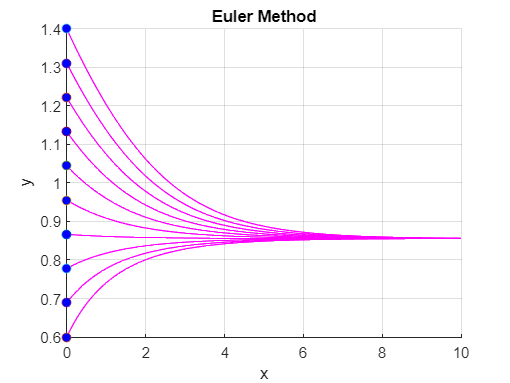

% Iterate over the initial conditions
figure; hold on
for x0 = initial_conditions
    % Implement our function 'MyEuler'
    [t1,x1] = MyEuler(x0,t0,tf,nPts,fx_Anon1);
    % Plot the results
    plot(t1,x1,'m')
    plot(0,x0,'o','MarkerFaceColor','b');
    xlabel('x'); ylabel('y'); grid on;
    title('Euler Method');
end
hold off

b) Runge-Kutta Method.

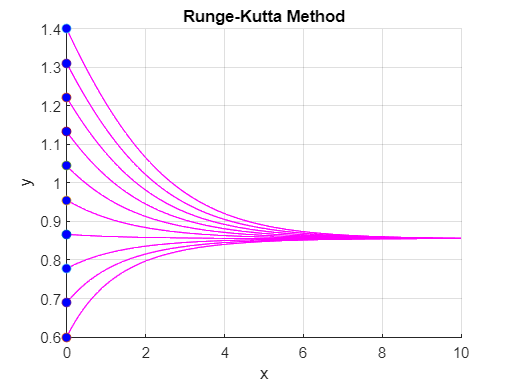

figure; hold on
for x0 = initial_conditions
    % Implement our function 'MyRungeKutta'
    [t2,x2] = MyRungeKutta(x0,t0,tf,nPts,fx_Anon1);
    % Plot the results
    plot(t2,x2,'m')
    plot(0,x0,'o','MarkerFaceColor','b');
    xlabel('x'); ylabel('y'); grid on;
    title('Runge-Kutta Method');
end
hold off

### Question 2

close all; clc; clear;
syms x(t) t

disp('Question 2');

Question 2


% write the differential equation
dx2 = diff(x,t,2);
dx = diff(x,t);
EQN = dx2 - 2*dx -3*x == 2*exp(-3*t) + 3*exp(-t)

$$EQN(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-2\,\frac{\partial }{\partial t}x\left(t\right)-3\,x\left(t\right)=3\,{\mathrm{e}}^{-t}+2\,{\mathrm{e}}^{-3\,t}$$

a) General Solution.

disp('General Solution:')

General Solution:


xsol_gen = dsolve(EQN)

$$xsol\_gen = C_{1}\,{\mathrm{e}}^{-t}-\frac{{\mathrm{e}}^{-3\,t}\,\left(9\,{\mathrm{e}}^{2\,t}+4\right)}{48}-{\mathrm{e}}^{-t}\,\left(\frac{3\,t}{4}-\frac{{\mathrm{e}}^{-2\,t}}{4}\right)+C_{2}\,{\mathrm{e}}^{3\,t}$$

b) Particular solution for x(0) = 0 and dx/dt = 1.

% Put the Initial Conditiont0 = ?; 
cond = [x(0) == 0, dx(0) == 1];
% Solving the differential equation
disp('Particular solution for x(0) = 0 and dx/dt = 1:')

Particular solution for x(0) = 0 and dx/dt = 1:


xsol_par = dsolve(EQN,cond)

$$xsol\_par = -\frac{{\mathrm{e}}^{-3\,t}\,\left(33\,{\mathrm{e}}^{2\,t}-25\,{\mathrm{e}}^{6\,t}+36\,t\,{\mathrm{e}}^{2\,t}-8\right)}{48}$$

c) Plotting the Particular Solution.

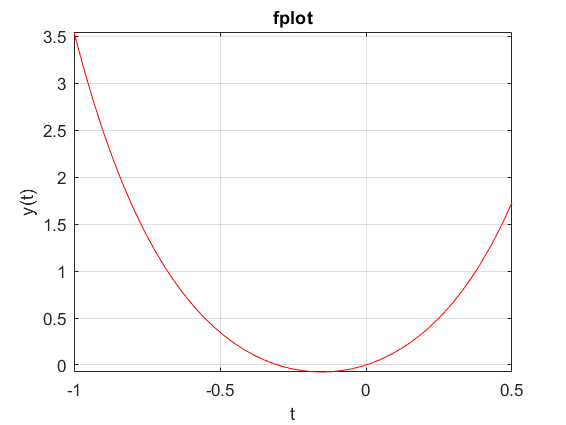

figure; fplot(xsol_par,[-1, 1/2],'r');
xlabel('t');ylabel('y(t)');grid on; title('fplot')

d) Analizar la parte homogénea del sistema. Puntos Fijos y clasificación de la misma.

syms t x y

% First the system was rewrote in the way: dx/dt = Ax
A = [0,1;3,2];

% Definir la ecuación para los puntos fijos A*[x; y] = [x; y]
eq1 = A(1,1)*x + A(1,2)*y - x == 0;
eq2 = A(2,1)*x + A(2,2)*y - y == 0;

% Resolver el sistema de ecuaciones para encontrar los puntos fijos
sol = solve([eq1, eq2], [x, y]);

% Mostrar los puntos fijos
disp('Fixed points of the homogeneous equation:')

Fixed points of the homogeneous equation:


disp(sol);

    x: 0
    y: 0




detA = det(A);
traA = trace(A);
[eigVecA,eigValA] = eig(A);
eigValA = diag(eigValA);
parab = traA^2-4*detA;

if detA<0
    disp('Saddle Point')
    disp('EigenValues:');eigValA
    disp('EigenVectors:');eigVecA
elseif detA == 0
    disp('Non-Isolated Fixed Point');
    if traA>0
        disp('Unstable Line of Fixed Points')
        %1º) Provide the direction of the unstable fixed points
        nonZeroEigenvalueIndex = find(eigValA ~= 0);
        eigenvector = eigVecA(:, nonZeroEigenvalueIndex);
        disp("Direction of the unstable fixed point");eigenvector
    elseif traA<0
        disp('Non-Isolated Fixed Point')
        %1º) Provide the direction of the stable fixed points
       nonZeroEigenvalueIndex = find(eigValA ~= 0);
       eigenvector = eigVecA(:, nonZeroEigenvalueIndex);
       disp("Direction");eigenvector
    else
        disp('Plane of Fixed Points')
    end
else
    if traA == 0 % Center zone
        disp('Center');
    elseif traA > 0 % Stable zone
        if parab > 0
            disp('Unstable Node')
             %1º) Provide the directions of the slower and faster
             %eigenvalues
           [slowerEigenvalue, index] = min(abs(eigValA));
            slowerEigenvector = eigVecA(:, index)
            fasterEigenvalue = eigValA(3 - index); % Assuming you have 2 eigenvalues
            fasterEigenvector = eigVecA(:, 3 - index);
            disp("Direction of the faster eigenvalue ");fasterEigenvector
            disp("Direction of the slower eigenvalue");slowerEigenvector
        elseif parab ==0
            disp('Unstable star or Unstable Degenerated Node')
            disp("------------------------------------------")
             % 1º) Distinguish both cases
             %In the case we have two indpendent eigenvectors---> STAR
             eigVecmatrix = [eigVecA(:,1),eigVecA(:,2)]
             determinantA = det(eigVecmatrix)
             threshold = 1e-10;
             if determinantA > threshold
                 disp('The eigenvectors are linearly independent. Therfore we have a star');
                 
             else
                 disp("The eigenvectors are linearly dependent. Therfore we have a degenerated node");
                 % 2º) Provide the eigenvector of the degenerated node it is the% case.
                 disp("The direction of the eigenvector is:");eigVecA(:,1)
             end
   
             
        else
            disp('Unstable Spiral')
        end
    else % Stable zone
        if parab > 0
            disp('Stable NODE')
             %1º) Provide the directions of the slower and faster
             %eigenvalues
            [slowerEigenvalue, index] = min(abs(eigValA));
            slowerEigenvector = eigVecA(:, index)
            fasterEigenvalue = eigValA(3 - index); % Assuming you have 2 eigenvalues
            fasterEigenvector = eigVecA(:, 3 - index);
            disp("Direction of the faster eigenvalue ");fasterEigenvector
            disp("Direction of the slower eigenvalue");slowerEigenvector
             
        elseif parab ==0
            disp('Stable start or Degenerated Node')
             % 1º) Distinguish both cases
             eigVecmatrix = [eigVecA(:,1);eigVec2(:,2)];
             determinantA = det(eigVecmatrix);
             threshold = 1e-10;
             if determinantA > threshold
                 disp('The eigenvectors are linearly independent. Therfore we have a stable star');
                 
             else
                 disp("The eigenvectors are dependent. Therfore we have a stable degenerated node");
                 % 2º) Provide the eigenvector of the degenerated node it is the% case.
                 disp("The direction of the eigenvector is:");eigVecA(:,1)
             end
        else
            disp('Stable Spiral')
        end
    end

end

Saddle Point


EigenValues:


eigValA =    -1.0000
    3.0000


EigenVectors:


eigVecA =    -0.7071   -0.3162
    0.7071   -0.9487


e) Stability.

disp('Unstable as it is a Saddle Point')

Unstable as it is a Saddle Point


### Pregunta 3

a)

clear t x(t)
syms t x y

disp('Question 3a');

Question 3a



% First the system was rewrote in the way: dx/dt = Ax
A = [-3,2;1,-2];

% Definir la ecuación para los puntos fijos A*[x; y] = [x; y]
eq1 = A(1,1)*x + A(1,2)*y - x == 0;
eq2 = A(2,1)*x + A(2,2)*y - y == 0;

% Resolver el sistema de ecuaciones para encontrar los puntos fijos
sol = solve([eq1, eq2], [x, y]);

% Mostrar los puntos fijos
disp('Puntos Fijos')

Puntos Fijos


disp(sol);

    x: 0
    y: 0




detA = det(A);
traA = trace(A);
[eigVecA,eigValA] = eig(A);
eigValA = diag(eigValA);
parab = traA^2-4*detA;

if detA<0
    disp('Saddle Point')
    disp('EigenValues:');eigValA
    disp('EigenVectors:');eigVecA
elseif detA == 0
    disp('Non-Isolated Fixed Point');
    if traA>0
        disp('Unstable Line of Fixed Points')
        %1º) Provide the direction of the unstable fixed points
        nonZeroEigenvalueIndex = find(eigValA ~= 0);
        eigenvector = eigVecA(:, nonZeroEigenvalueIndex);
        disp("Direction of the unstable fixed point");eigenvector
    elseif traA<0
        disp('Non-Isolated Fixed Point')
        %1º) Provide the direction of the stable fixed points
       nonZeroEigenvalueIndex = find(eigValA ~= 0);
       eigenvector = eigVecA(:, nonZeroEigenvalueIndex);
       disp("Direction");eigenvector
    else
        disp('Plane of Fixed Points')
    end
else
    if traA == 0 % Center zone
        disp('Center');
    elseif traA > 0 % Stable zone
        if parab > 0
            disp('Unstable Node')
             %1º) Provide the directions of the slower and faster
             %eigenvalues
           [slowerEigenvalue, index] = min(abs(eigValA));
            slowerEigenvector = eigVecA(:, index)
            fasterEigenvalue = eigValA(3 - index); % Assuming you have 2 eigenvalues
            fasterEigenvector = eigVecA(:, 3 - index);
            disp("Direction of the faster eigenvalue ");fasterEigenvector
            disp("Direction of the slower eigenvalue");slowerEigenvector
        elseif parab ==0
            disp('Unstable star or Unstable Degenerated Node')
            disp("------------------------------------------")
             % 1º) Distinguish both cases
             %In the case we have two indpendent eigenvectors---> STAR
             eigVecmatrix = [eigVecA(:,1),eigVecA(:,2)]
             determinantA = det(eigVecmatrix)
             threshold = 1e-10;
             if determinantA > threshold
                 disp('The eigenvectors are linearly independent. Therfore we have a star');
                 
             else
                 disp("The eigenvectors are linearly dependent. Therfore we have a degenerated node");
                 % 2º) Provide the eigenvector of the degenerated node it is the% case.
                 disp("The direction of the eigenvector is:");eigVecA(:,1)
             end
   
             
        else
            disp('Unstable Spiral')
        end
    else % Stable zone
        if parab > 0
            disp('Stable NODE')
             %1º) Provide the directions of the slower and faster
             %eigenvalues
            [slowerEigenvalue, index] = min(abs(eigValA));
            slowerEigenvector = eigVecA(:, index)
            fasterEigenvalue = eigValA(3 - index); % Assuming you have 2 eigenvalues
            fasterEigenvector = eigVecA(:, 3 - index);
            disp("Direction of the faster eigenvalue ");fasterEigenvector
            disp("Direction of the slower eigenvalue");slowerEigenvector
             
        elseif parab ==0
            disp('Stable start or Degenerated Node')
             % 1º) Distinguish both cases
             eigVecmatrix = [eigVecA(:,1);eigVec2(:,2)];
             determinantA = det(eigVecmatrix);
             threshold = 1e-10;
             if determinantA > threshold
                 disp('The eigenvectors are linearly independent. Therfore we have a stable star');
                 
             else
                 disp("The eigenvectors are dependent. Therfore we have a stable degenerated node");
                 % 2º) Provide the eigenvector of the degenerated node it is the% case.
                 disp("The direction of the eigenvector is:");eigVecA(:,1)
             end
        else
            disp('Stable Spiral')
        end
    end

end

Stable NODE


slowerEigenvector =    -0.7071
   -0.7071


Direction of the faster eigenvalue 


fasterEigenvector =    -0.8944
    0.4472


Direction of the slower eigenvalue


slowerEigenvector =    -0.7071
   -0.7071


b)

% Phase Portrait
disp('Question 3b');

Question 3b


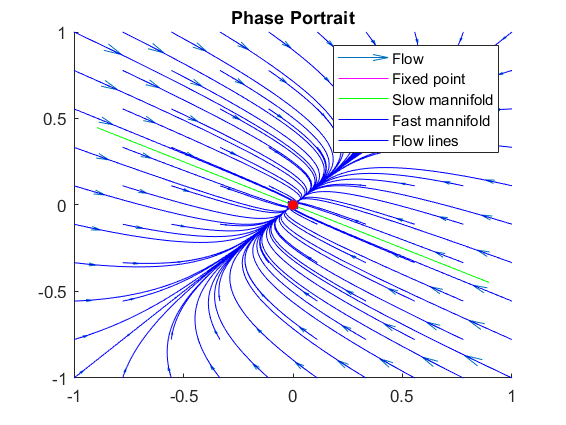


detA = det(A);
traA = trace(A);
[eigVecA,eigValA] = eig(A);
eigValA = diag(eigValA);
parab = traA^2-4*detA;

N = 10; % size of grid
xlin = linspace(-1,1,N); ylin = linspace(-1,1,N);
[Xgrid,Ygrid] = meshgrid(xlin,ylin);

Xgrid_v = Xgrid(:);Ygrid_v = Ygrid(:);
Flowgrid_v = transpose(A*transpose([Xgrid_v,Ygrid_v]));

h1 = figure;hold on;
%plot(Xgrid_v,Ygrid_v,'r.');
quiver(Xgrid_v,Ygrid_v,Flowgrid_v(:,1),Flowgrid_v(:,2))
start_x = linspace(-1, 1, 10);
start_y = linspace(-1, 1, 10);
[start_X, start_Y] = meshgrid(start_x, start_y);
%Lo necesitaremos para las líneas de flujo
u = reshape(Flowgrid_v(:,1), N, N);
v = reshape(Flowgrid_v(:,2), N, N);
title('Phase Portrait');

% Fixed point
fxpts = [0;0];
figure(h1);

% ¿What happend if there is more than one? Plot it using a flag in the
% clasification 
if detA == 0
    disp("There is a line of fixed points---> Infinite amount of fixed points");
    
end

% Straight Trajetories in nodes (eigenvectors)
t = linspace(-1,1);
[~,minI] = min(abs(eigValA));
[~,maxI] = max(abs(eigValA));
strLineMin = t.*eigVecA(:,minI);
strLineMax = t.*eigVecA(:,maxI);
%New trayectories with line of fixed points
if detA == 0
    disp("There is a line of fixed points");
    % Lower eigenvalue
    plot(strLineMin(1,:),strLineMin(2,:),'m');
    plot(strLineMax(1,:),strLineMax(2,:),'g');
    legend("Flow","Fixed point","Slow mannifold", "Fast mannifold", "Flow lines", AutoUpdate= "off");
    for value = -1:0.2:1
        %PLOT THE LINES OF THE LINE OF FIXED POINTS
        NewLineMax = t.*eigVecA(:,maxI) + value;
        plot(NewLineMax(1,:), strLineMax(2,:), "g");
    end

    %HACER INFINITAS LINEAS PARALERLAS
else
    % Lower eigenvalue
    plot(strLineMin(1,:),strLineMin(2,:),'m');
    plot(strLineMax(1,:),strLineMax(2,:),'g');
    % Trazar las líneas de flujo
    streamline(Xgrid, Ygrid, u, v, start_X, start_Y)
    legend("Flow", "Fixed point", "Slow mannifold", "Fast mannifold","Flow lines", AutoUpdate = "off")
end
plot(fxpts(1),fxpts(2),'o','MarkerFaceColor','r');

c)

disp('Question 3c')

Question 3c


% Bidimensional Linear System
clear x y
syms t x(t) y(t)

% Symbolic
dx = diff(x); dy = diff(y);
eqn = [dx;dy] == A*[x;y];
solg = dsolve(eqn)

solg = struct with fields:
    y: C1*exp(-t) + C2*exp(-4*t)
    x: C1*exp(-t) - 2*C2*exp(-4*t)


d)

disp('Question 3d')

Question 3d


disp('Solving systems for initial condition x(0)=0, y(0)=1')

Solving systems for initial condition x(0)=0, y(0)=1


t0 = 0

t0 = 0

xy0 = [0;1];
solp = dsolve(eqn,[x(t0);y(t0)]==xy0)

solp = struct with fields:
    y: (2*exp(-t))/3 + exp(-4*t)/3
    x: (2*exp(-t))/3 - (2*exp(-4*t))/3


xp = solp.x; yp = solp.y;
xpts = double(subs(xp,t,linspace(0,0.5,100)));
ypts = double(subs(yp,t,linspace(0,0.5,100)));


### Question 4

clear x(t) y(t) t;

disp('Question 4')

Question 4



syms x r
assume(x, 'real')

% Dynamic System
% Define the function here
disp('Dynamic System to be analyzed')

Dynamic System to be analyzed


fx = -x*(x^2-r*x+1)

$$fx = -x\,\left(x^{2}-r\,x+1\right)$$


% Compute the derivative once
df = diff(fx, x);

% Convert symbolic functions to anonymous functions for faster evaluation
fx = matlabFunction(fx, 'Vars', [r, x]);
df = matlabFunction(df, 'Vars', [r, x]);

% Compute the fixed points with respect to the control parameter 'r'
display('Possible Fixed Points:')

Possible Fixed Points:


Fpts = solve(fx, x)

$$Fpts = \left(\begin{array}{c} 0\\ \frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}\\ \frac{r}{2}+\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2} \end{array}\right)$$


% Determine the number of fixed points
possible_n_fpts = length(Fpts);
display(['Maximum number of possible Fixed Points:', num2str(possible_n_fpts)])

Maximum number of possible Fixed Points:3



eps = 1e-3;

% Lists for number of fixed points
prev_n_fpts = -5;
n_fpts = [];
% List for r values when a bifurcation occur (nº of FP change)
r_values = [];
% List for Stable and Unstable FP
stable_x_values = [];
unstable_x_values = [];
% List for values of r, for Stable and Unstable FP
r_stable = [];
r_unstable = [];

% Loop over all r values
rV = linspace(-10, 10, 500);
rV_int = -10:1:10;
rValues = sort(unique([rV, rV_int]));
for r_trial = rValues
    
    Fpts_sub = PossibleFixedPoints(Fpts, r_trial, r);
    
    % Calculate the number of Fixed Points
    n_fpts_r = length(Fpts_sub);

    % If the number of fixed points has changed, add the corresponding r value
    if n_fpts_r ~= prev_n_fpts
        r_values = [r_values, r_trial];
        n_fpts = [n_fpts, n_fpts_r];
        % Update the previous number of fixed points for the next iteration
        prev_n_fpts = n_fpts_r;
    end

    % Calculate the derivative at Fixed Points
    dfx_Fpts = df(r_trial, Fpts_sub);
   
    stb_pts = Fpts_sub(dfx_Fpts < 0);
    nstb_pts = Fpts_sub(dfx_Fpts > 0);
    for k=1:length(stb_pts)
        stable_x_values = [stable_x_values, stb_pts(k)];
    end
    for k=1:length(nstb_pts)
        unstable_x_values = [unstable_x_values, nstb_pts(k)];
    end
    % Esta es la forma de appending values to the list
    r_stable = [r_stable, r_trial*ones(1, length(stb_pts))];
    r_unstable = [r_unstable, r_trial*ones(1, length(nstb_pts))];
end

% Mostrar las zonas de bifurcación y el número de puntos fijos en cada zona
% r_values -> bifurcation points

% rValues -> trial r values
% n_fpts -> nº of FP for each zone

% z_r_trial -> representative values of each zone and bifurcation points
z_r_trial = r_zones(r_values, rValues, n_fpts);

Zona 1: -10.00 <= r <= -2.00, el número de puntos fijos es 3
Zona 2: -2.00 <= r <= -2.00, el número de puntos fijos es 2
Zona 3: -2.00 <= r <= 2.00, el número de puntos fijos es 1
Zona 4: 2.00 <= r <= 2.00, el número de puntos fijos es 2
Zona 5: 2.00 <= r <= 10.00, el número de puntos fijos es 3
Valores de r representativos para cada zona:
    -6
    -2
     0
     2
     6

Puntos de bifurcación:
    -2     2



Zona 1: r = -6.00

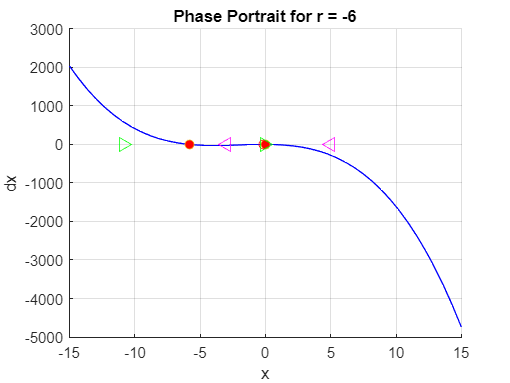

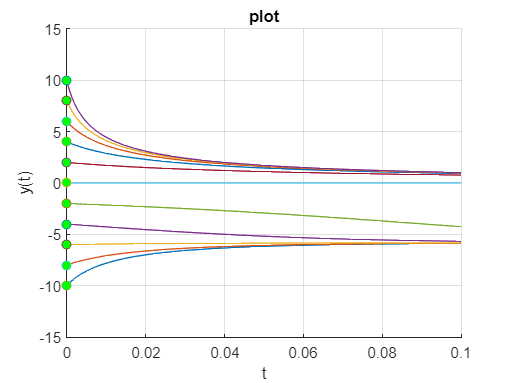

Zona 2: r = -2.00

There is a Mixed Fixed Point at x = -2I know it seems to be an unstable as it is drawn as one, but i did not know how to fill half of it to make it Mixed. If you have any improve please tell me.

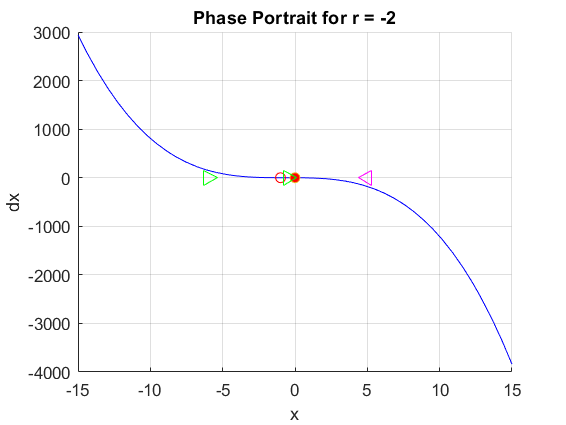

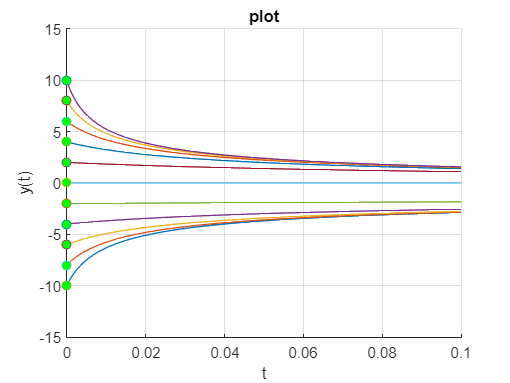

Zona 3: r = 0.00

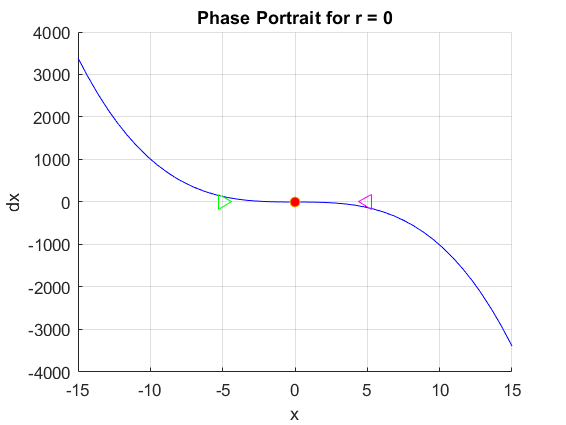

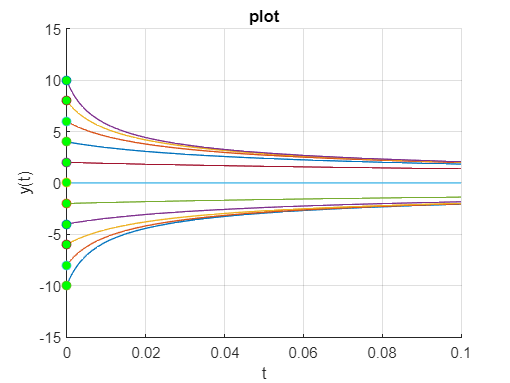

Zona 4: r = 2.00

There is a Mixed Fixed Point at x = 2I know it seems to be an unstable as it is drawn as one, but i did not know how to fill half of it to make it Mixed. If you have any improve please tell me.

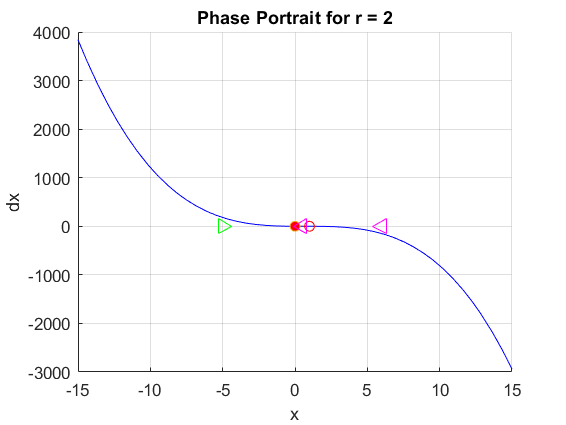

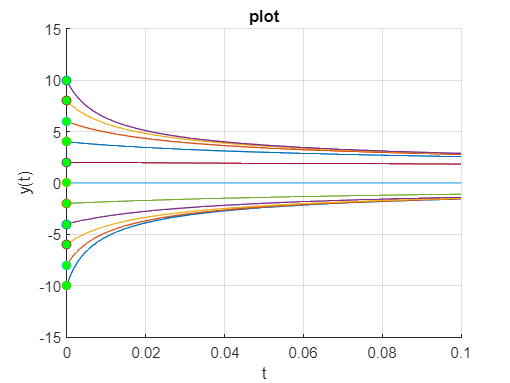

Zona 5: r = 6.00

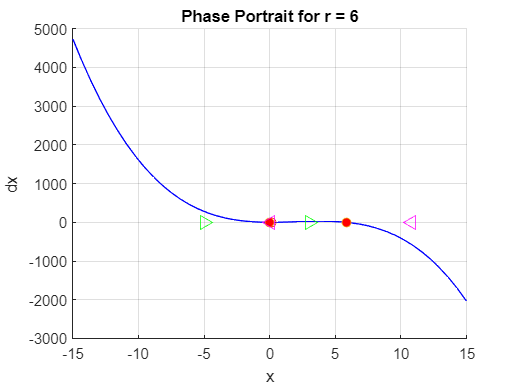

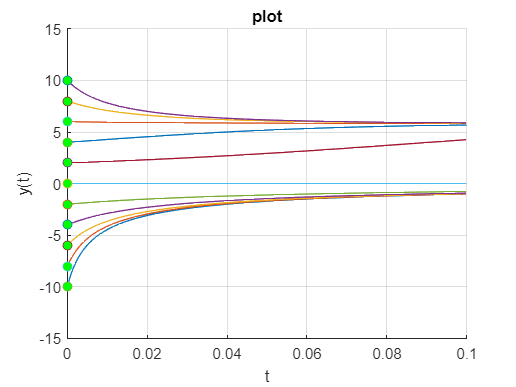

for k = 1:length(z_r_trial)
    fprintf('Zona %d: r = %.2f', k, z_r_trial(k));
    PhasePortrait(fx, Fpts, z_r_trial(k), r, x)
end

% We see the bifurcation points in the plot above
bif_pts = [2, -2]

bif_pts =      2    -2


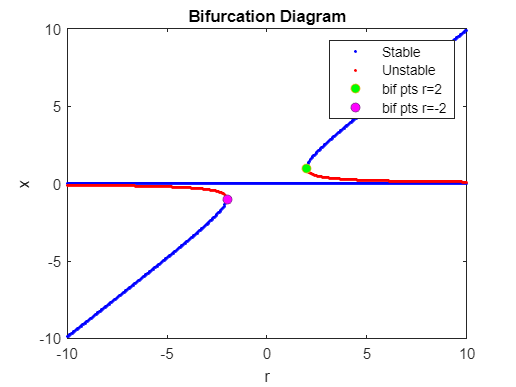


% Plot bifurcation diagram
figure('Name', 'Bifurcation Diagram', 'NumberTitle', 'off');
plot(r_stable, stable_x_values, 'b.', 'DisplayName', 'Stable');
hold on;
plot(r_unstable, unstable_x_values, 'r.', 'DisplayName', 'Unstable');

% Plot bifurcation points
plot(bif_pts(1), 1, 'o', 'MarkerFaceColor', 'g', 'DisplayName', 'bif pts r=2')
plot(bif_pts(2), -1,'o', 'MarkerFaceColor', 'm', 'DisplayName', 'bif pts r=-2')

title('Bifurcation Diagram');
xlabel('r');
ylabel('x');
legend();
hold off;


disp('Bifurcation point at r=-2, end of a saddle node')

Bifurcation point at r=-2, end of a saddle node


disp('Bifurcation point at r=2, begin of a saddle node')

Bifurcation point at r=2, begin of a saddle node


disp('Both saddle nodes and the fixed point at x=0, are the result of an imperfect (perturbated) transcritical bifurcation')

Both saddle nodes and the fixed point at x=0, are the result of an imperfect (perturbated) transcritical bifurcation
